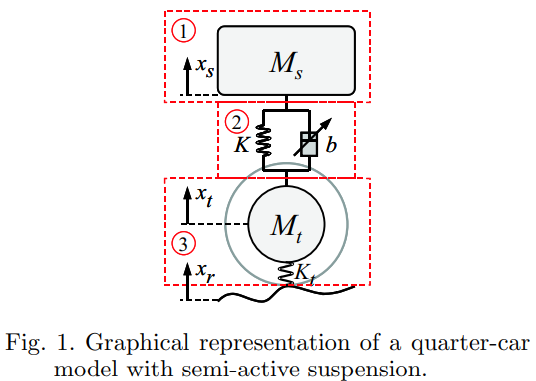

We use the above quater car mode with the following parameters


$$m_s =2\ldotp 45\;\mathrm{kg};K=980\;\frac{N}{m};$$

$$b=7\ldotp 5\;\frac{\mathrm{Ns}}{s}$$



$$m_t =1\;\mathrm{kg};K_t =2500\;\frac{N}{m};$$



$$x_r =x_{\mathrm{r0}\;} \sin \left(\mathrm{wt}\right);x_{\mathrm{r0}\;} =10;\;w=2$$


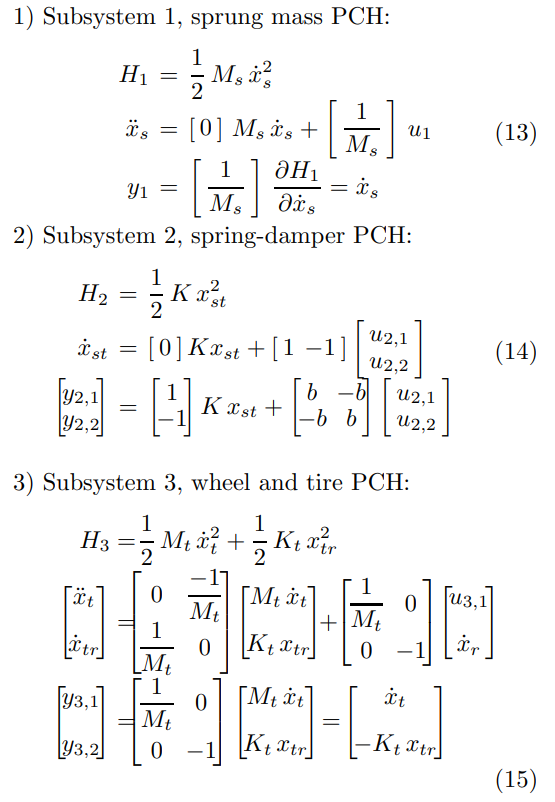

We define the state space form for the above 3 subsystems as follows (considering b is constant with no control input Fc)

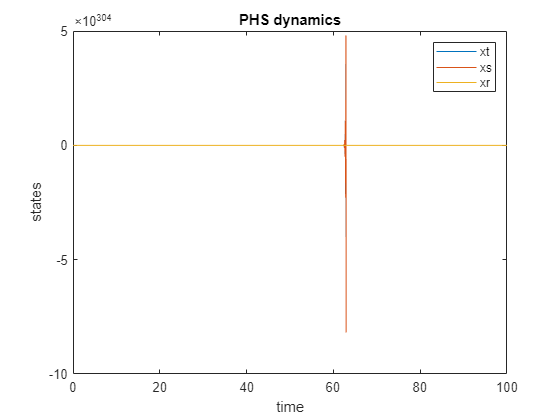

clc
clear
close all

tfinal = 100; t = 0; dt = 0.0001; % simulation parameters


ms=2.45; K=980; b=7.5;
mt=1; Kt=2500;
xr0=10; w=2;

A_PHS1 = 0; B_PHS1 = 1/ms; C_PHS1 = 1/ms; 
A_PHS2 = 0; B_PHS2 = [1 -1]; C_PHS2 = [1;-1]; D_PHS2 = [b -b;-b b];
A_PHS3 = [0 -1/mt;1/mt 0]; B_PHS3 = [1/mt 0;0 -1]; C_PHS3 = [1/mt 0;0 -1];
x_des = 10; lambda = -1;


phs10=10; phs1=phs10; 
y1=C_PHS1*phs1; u1=0;

phs20=10; phs2=phs20; 
y21=0; y22=0; y2=[y21;y22];
y2=C_PHS2*phs2; u21=0; u22=0;

phs30=[1;1]; phs3=phs30;
y31=0; y32=0; y3=[y31;y32];
y3=C_PHS3*phs3; u31=0;

xt0=1; xt=xt0; 
xs0=10; xs=xs0;
xr=xr0*sin(w*t);

PHS1 = []; PHS2 = []; PHS3 = []; T = []; % initialize memory
Xt = []; Xs = []; Xr = [];
while (t <= tfinal)
    T = [T,t]; PHS1 = [PHS1,phs1]; PHS2 = [PHS2,phs2]; PHS3 = [PHS3,phs3];
    Xt = [Xt,xt]; Xs = [Xs,xs]; Xr = [Xr,xr];

    xr = xr0*sin(w*t);
    xr_dot = xr0*w*cos(w*t); 

    H1 = 0.5*ms*y1^2;    
    phs1 = phs1 + dt*(A_PHS1*(ms*phs1) + B_PHS1*u1);
    y1 = C_PHS1*(ms*phs1);

    H2 = 0.5*K*phs2^2;   
    phs2 = phs2 + dt*(A_PHS2*([K*phs2]) + B_PHS2*[u21;u22]);
    y2 = C_PHS2*(K*phs2) + D_PHS2*[u21;u22];
    xst = phs2;
    xs = xst + xt;

    H3 = 0.5*mt*y3(1)^2+0.5*Kt*(-y3(2)/Kt)^2;   
    phs3 = phs3 + dt*(A_PHS3*([mt*phs3(1);Kt*phs3(2)]) + B_PHS3*[u31; xr_dot]);
    y3 = C_PHS3*([mt*phs3(1);Kt*phs3(2)]); 
    xtr = phs3(2);
    xt = xr + xtr;


    u21 = y1; u1 = -y21;
    u22 = y31; u31 = -y22;

    H = H1+H2+H3;

    t = t + dt; % time increment
    
end

figure(1)
plot(T,Xt); hold on
plot(T,Xs); hold on
plot(T,Xr);
ylabel('states')
xlabel('time')
legend('xt','xs','xr')
title('PHS dynamics')

% figure(2)
% plot(T,EM); hold on;
% plot(T,EK); hold on;
% plot(T,ER.*ones(size(EM)));
% ylabel('PHS states')
% xlabel('time')
% legend('Em','Ek','Er')
% title('Energy dynamics')
% hold off
% PM = diff(EM)./diff(T);
% PK = diff(EK)./diff(T);
% PR = b*diff(Vsquare)./diff(T);

% figure(3)
% plot(T(2:end),PM); hold on;
% plot(T(2:end),PK); hold on;
% plot(T(2:end),PR);
% ylabel('Energy states')
% xlabel('time')
% legend('Pm','Pk','Pr')
% title('Power dynamics')
% hold off


